## 1.

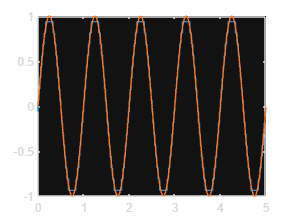

Ta = 0.002;
t = 0:Ta:5-Ta;
x = sin(2*pi*t);
amp = max(abs(x));%%amplitude
[X1,f1]=espetro(x,Ta);

for nbit= 2:4
    delta = (amp*2)/(2^nbit);
    
    partition = -amp+2*delta/2: delta:amp-delta/2;
    codebook = -amp+delta/2:delta:amp-delta/2;
    [index, quants] = quantiz(x,partition, codebook);
    
    plot(t,quants,t,x);
end

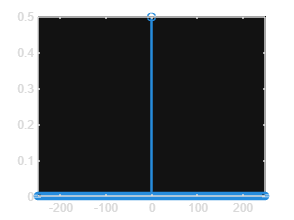

stem(f1,abs(X1)/length(x))